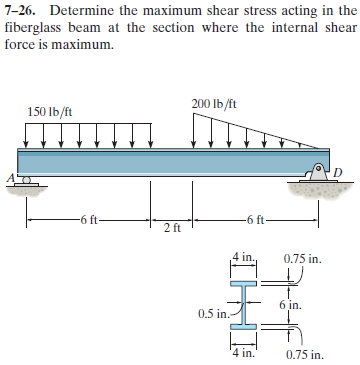

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-7-problem-26P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-7-problem-26P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# load data

x = sym('x');
w1(x) = -150*u.lbf/u.ft;
w2 = findpoly(1, 'thru', [8*u.ft -200*u.lbf/u.ft], 'thru', [14*u.ft 0]);

# beam

b = beam;
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('reaction', 'force', 'Rd', 14*u.ft);
b = b.add('distributed', 'force', w1, [0 6]*u.ft);
b = b.add('distributed', 'force', w2, [8 14]*u.ft);
b.L = 14*u.ft;

# section properties

yc = [3+0.75/2 3/2 -3/2 -3-0.75/2]*u.in;
Ac = [4*0.75 0.5*3 0.5*3 4*0.75]*u.in^2;
Ic = [4*0.75^3 0.5*3^3 0.5*3^3 4*0.75^3]/sym(12)*u.in^4;
[yn Qn In] = beam.neutral_axis(yc, Ac, Ic);
b.I = rewrite(sum(In), u.ft);

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} -\frac{7680\,x\,\left(35\,x^{3}-820\,x^{2}\,\mathrm{ft}+71464\,{\mathrm{ft}}^{3}\right)}{161\,\text{E}}\,\frac{\mathrm{lbf}}{{\mathrm{ft}}^{5}} & \text{ if }x\leq 6\,\mathrm{ft}\\ -\frac{30720\,\left(5\,x^{3}-1890\,x^{2}\,\mathrm{ft}+25426\,x\,{\mathrm{ft}}^{2}-11340\,{\mathrm{ft}}^{3}\right)}{161\,\text{E}}\,\frac{\mathrm{lbf}}{{\mathrm{ft}}^{4}} & \text{ if }x\in \left(6\,\mathrm{ft},8\,\mathrm{ft}\right]\\ \frac{5120\,\left(x-14\,\mathrm{ft}\right)\,\left(7\,x^{4}-392\,x^{3}\,\mathrm{ft}+5622\,x^{2}\,{\mathrm{ft}}^{2}-3752\,x\,{\mathrm{ft}}^{3}+63244\,{\mathrm{ft}}^{4}\right)}{483\,\text{E}}\,\frac{\mathrm{lbf}}{{\mathrm{ft}}^{6}} & \text{ if }8\,\mathrm{ft}<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} -\frac{30720\,\left(35\,x^{3}-615\,x^{2}\,\mathrm{ft}+17866\,{\mathrm{ft}}^{3}\right)}{161\,\text{E}}\,\frac{\mathrm{lbf}}{{\mathrm{ft}}^{5}} & \text{ if }x\leq 6\,\mathrm{ft}\\ -\frac{30720\,\left(15\,x^{2}-3780\,x\,\mathrm{ft}+25426\,{\mathrm{ft}}^{2}\right)}{161\,\text{E}}\,\frac{\mathrm{lbf}}{{\mathrm{ft}}^{4}} & \text{ if }x\in \left(6\,\mathrm{ft},8\,\mathrm{ft}\right]\\ \frac{5120\,\left(35\,x^{4}-1960\,x^{3}\,\mathrm{ft}+33330\,x^{2}\,{\mathrm{ft}}^{2}-164920\,x\,{\mathrm{ft}}^{3}+115772\,{\mathrm{ft}}^{4}\right)}{483\,\text{E}}\,\frac{\mathrm{lbf}}{{\mathrm{ft}}^{6}} & \text{ if }8\,\mathrm{ft}<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} -\frac{75\,x\,\left(7\,x-82\,\mathrm{ft}\right)}{7}\,\frac{\mathrm{lbf}}{\mathrm{ft}} & \text{ if }x\leq 6\,\mathrm{ft}\\ -\frac{150\,\left(x-126\,\mathrm{ft}\right)}{7}\,\mathrm{lbf} & \text{ if }x\in \left(6\,\mathrm{ft},8\,\mathrm{ft}\right)\\ \frac{50\,\left(x-14\,\mathrm{ft}\right)\,\left(7\,x^{2}-196\,x\,\mathrm{ft}+589\,{\mathrm{ft}}^{2}\right)}{63}\,\frac{\mathrm{lbf}}{{\mathrm{ft}}^{2}} & \text{ if }8\,\mathrm{ft}\leq x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} -\frac{150\,\left(7\,x-41\,\mathrm{ft}\right)}{7}\,\frac{\mathrm{lbf}}{\mathrm{ft}} & \text{ if }x\leq 6\,\mathrm{ft}\\ -\frac{150}{7}\,\mathrm{lbf} & \text{ if }x\in \left(6\,\mathrm{ft},8\,\mathrm{ft}\right)\\ \frac{50\,\left(7\,x^{2}-196\,x\,\mathrm{ft}+1111\,{\mathrm{ft}}^{2}\right)}{21}\,\frac{\mathrm{lbf}}{{\mathrm{ft}}^{2}} & \text{ if }8\,\mathrm{ft}\leq x \end{array}\right.$$

w

$$w(x) = \left\{ \begin{array}{cl} -150\,\frac{\mathrm{lbf}}{\mathrm{ft}} & \text{ if }x\leq 6\,\mathrm{ft}\\ 0 & \text{ if }x\in \left(6\,\mathrm{ft},8\,\mathrm{ft}\right)\\ \frac{100\,\left(x-14\,\mathrm{ft}\right)}{3}\,\frac{\mathrm{lbf}}{{\mathrm{ft}}^{2}} & \text{ if }8\,\mathrm{ft}\leq x \end{array}\right.$$

# reactions and hinges

ra_vpa = vpa(ra, 5) %#ok<NASGU> 

$$ra\_vpa = \left(\begin{array}{cc} \mathrm{Ra} & 878.57\,\mathrm{lbf}\\ \mathrm{Rd} & 621.43\,\mathrm{lbf} \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagram

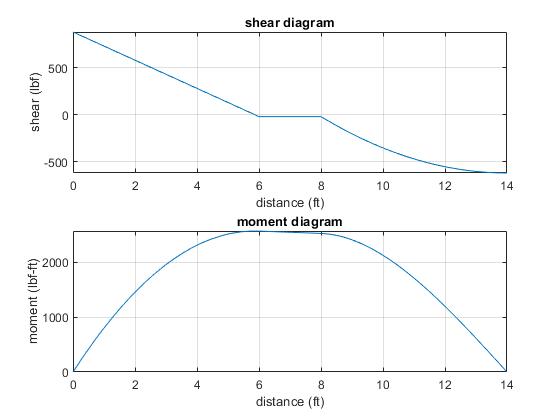

beam.shear_moment(m, v, [0 b.L], {'lbf' 'ft'});

# absolute maximum shear stress

V_max = v(0);
Q_max = sum(Qn(1:2));
b.I = rewrite(b.I, u.in);
t_min = 0.5*u.in;
tau_max = rewrite(V_max*Q_max/(b.I*t_min), u.psi);
tau_max_vpa = vpa(tau_max, 5) %#ok<NASGU> 

$$tau\_max\_vpa = 280.12\,\mathrm{psi}$$

# clean up

addvar(y);
assume(old_assum);
clear old_assum;
clear ra_vpa;
clear tau_max_vpa;